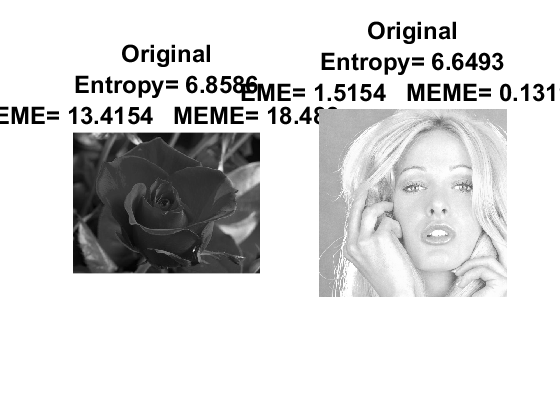

%Loading img and displaying a EME and MEME 
close all; figure;
img1 = imread('Images/Rose.jpg');
img2 = imread('Images/TiffanyOriginal.png');
imgEnchanced1 = ContrastEnhancement(img1);
imgEnchanced2 = ContrastEnhancement(img2);
imgHisteq1   = histeq(img1);
imgHisteq2   = histeq(img2);
subplot(1,2,1)
imshow(img1);
title([{"\fontsize{18}Original"};{"\fontsize{18}Entropy= "+entropy(img1)};{"\fontsize{18}EME= "+EME(img1)+"   MEME= "+MEME(img1)}]);
subplot(1,2,2)
imshow(img2);
title([{"\fontsize{18}Original"};{"\fontsize{18}Entropy= "+entropy(img2)};{"\fontsize{18}EME= "+EME(img2)+"   MEME= "+MEME(img2)}]);

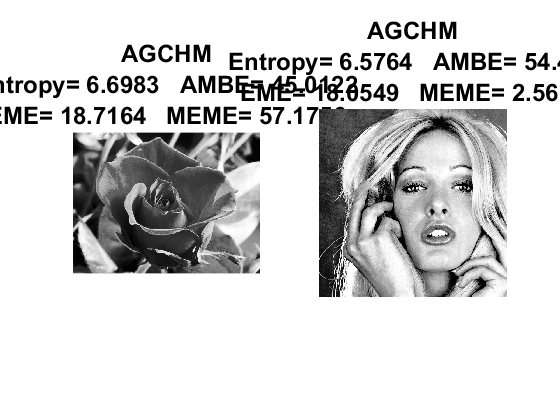

figure;
%h_m (k)=c(h_i (k)+δ)^γ)
%δ=√(1/K ∑_(k=0)^(K-1)▒[h_i (k)-u ̃ ]^2 ) => STD
subplot(1,2,1)
imshow(imgEnchanced1);
title([{"\fontsize{18}AGCHM"};{"\fontsize{18}Entropy= "+entropy(imgEnchanced1)+"   AMBE= "+AMBE(img1,imgEnchanced1)};{"\fontsize{18}EME= "+EME(imgEnchanced1)+"   MEME= "+MEME(imgEnchanced1)}]);
subplot(1,2,2)
imshow(imgEnchanced2);
title([{"\fontsize{18}AGCHM"};{"\fontsize{18}Entropy= "+entropy(imgEnchanced2)+"   AMBE= "+AMBE(img2,imgEnchanced2)};{"\fontsize{18}EME= "+EME(imgEnchanced2)+"   MEME= "+MEME(imgEnchanced2)}]);

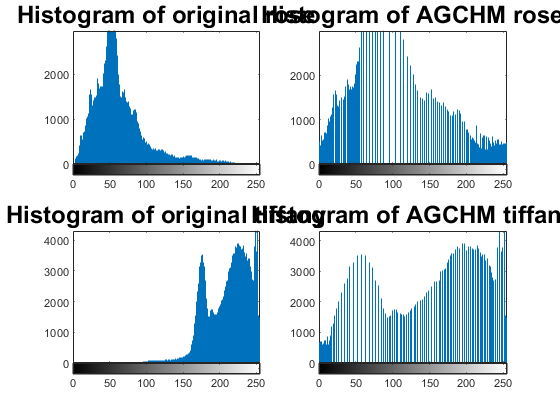

figure;
subplot(2,2,1);
imhist(img1);
title('\fontsize{18}Histogram of original rose');
subplot(2,2,2);
imhist(imgEnchanced1);
title('\fontsize{18}Histogram of AGCHM rose');
subplot(2,2,3);
imhist(img2);
title('\fontsize{18}Histogram of original tiffany');
subplot(2,2,4);
imhist(imgEnchanced2);
title('\fontsize{18}Histogram of AGCHM tiffany');

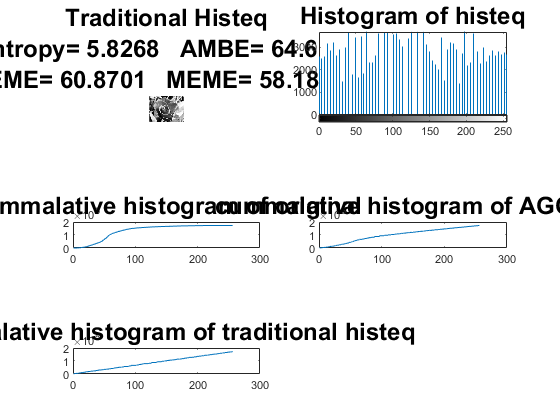

figure;
subplot(3,2,1);
imshow(imgHisteq1);
title([{"\fontsize{18}Traditional Histeq"};{"Entropy= "+entropy(imgHisteq1)+"   AMBE= "+AMBE(img1,imgHisteq1)};{"\fontsize{18}EME= "+EME(imgHisteq1)+"   MEME= "+MEME(imgHisteq1)}]);
subplot(3,2,2);
imhist(imgHisteq1);
title('\fontsize{18}Histogram of histeq');
subplot(3,2,3);
plot(cumsum(imhist(img1)));
title('\fontsize{18}cummalative histogram of original');
subplot(3,2,4);
plot(cumsum(imhist(imgEnchanced1)));
title('\fontsize{18}cummalative histogram of AGCHM');
subplot(3,2,5);
plot(cumsum(imhist(imgHisteq1)));
title('\fontsize{18}cummalative histogram of traditional histeq');

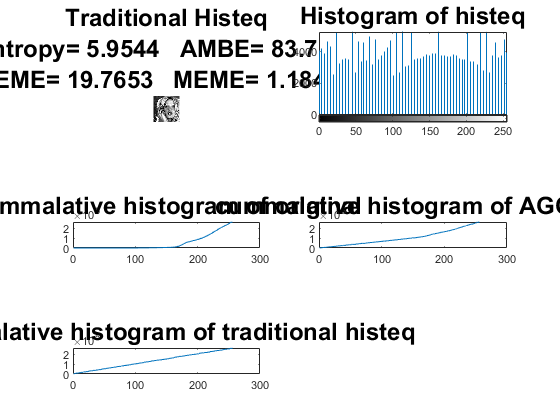

figure;
subplot(3,2,1);
imshow(imgHisteq2);
title([{"\fontsize{18}Traditional Histeq"};{"Entropy= "+entropy(imgHisteq2)+"   AMBE= "+AMBE(img2,imgHisteq2)};{"\fontsize{18}EME= "+EME(imgHisteq2)+"   MEME= "+MEME(imgHisteq2)}]);
subplot(3,2,2);
imhist(imgHisteq2);
title('\fontsize{18}Histogram of histeq');
subplot(3,2,3);
plot(cumsum(imhist(img2)));
title('\fontsize{18}cummalative histogram of original');
subplot(3,2,4);
plot(cumsum(imhist(imgEnchanced2)));
title('\fontsize{18}cummalative histogram of AGCHM');
subplot(3,2,5);
plot(cumsum(imhist(imgHisteq2)));
title('\fontsize{18}cummalative histogram of traditional histeq');

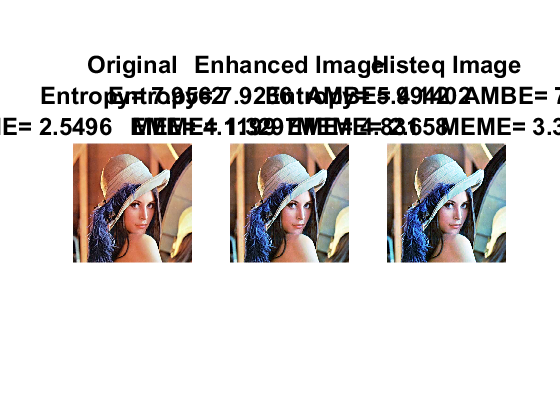


%Colorful Image
figure;

imgColor=imread(['Images\Lena.jfif']);

imgEnchancedColor=uint8(zeros(size(imgColor)));
imgHisteqColor=uint8(zeros(size(imgColor)));
for color=1:3
    imgEnchancedColor(:,:,color)=ContrastEnhancement(imgColor(:,:,color));
    imgHisteqColor(:,:,color)=histeq(imgColor(:,:,color));
end

subplot(1,3,1);
imshow(imgColor);
title([{"\fontsize{18}Original"};{"\fontsize{18}Entropy= "+entropy(imgColor)};{"\fontsize{18}EME= "+EME(imgColor)+"   MEME= "+MEME(imgColor)}]);
subplot(1,3,2);
imshow(imgEnchancedColor);
title([{"\fontsize{18}Enhanced Image"};{"\fontsize{18}Entropy= "+entropy(imgEnchancedColor)+"  AMBE= "+AMBE(imgColor,imgEnchancedColor)};{"\fontsize{18}EME= "+EME(imgEnchancedColor)+"   MEME= "+MEME(imgEnchancedColor)}]);
subplot(1,3,3);
imshow(imgHisteqColor);
title([{"\fontsize{18}Histeq Image"};{"\fontsize{18}Entropy= "+entropy(imgHisteqColor)+"  AMBE= "+AMBE(imgColor,imgHisteqColor)};{"\fontsize{18}EME= "+EME(imgHisteqColor)+"   MEME= "+MEME(imgHisteqColor)}]);

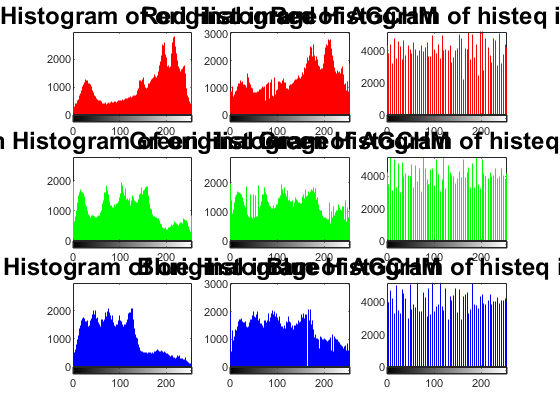

figure;
subplot(3,3,1);

imhist(imgColor(:,:,1));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to red
myHist.Color = [1 0 0];
title('\fontsize{18}Red Histogram of original image');
subplot(3,3,2);
imhist(imgEnchancedColor(:,:,1));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to red
myHist.Color = [1 0 0];
title('\fontsize{18}Red Histogram of AGCHM');
subplot(3,3,3);
imhist(imgHisteqColor(:,:,1));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to red
myHist.Color = [1 0 0];
title('\fontsize{18}Red Histogram of histeq image');
subplot(3,3,4);

imhist(imgColor(:,:,2));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to green
myHist.Color = [0 1 0];
title('\fontsize{18}Green Histogram of original image');
subplot(3,3,5);
imhist(imgEnchancedColor(:,:,2));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to green
myHist.Color = [0 1 0];
title('\fontsize{18}Green Histogram of AGCHM');
subplot(3,3,6);
imhist(imgHisteqColor(:,:,2));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to green
myHist.Color = [0 1 0];
title('\fontsize{18}Green Histogram of histeq image');
subplot(3,3,7);

imhist(imgColor(:,:,3));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to blue
myHist.Color = [0 0 1];
title('\fontsize{18}Blue Histogram of original image');
subplot(3,3,8);
imhist(imgEnchancedColor(:,:,3));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to blue
myHist.Color = [0 0 1];
title('\fontsize{18}Blue Histogram of AGCHM');
subplot(3,3,9);
imhist(imgHisteqColor(:,:,3));
myHist = findobj(gca, 'Type', 'Stem');
% Change the color to blue
myHist.Color = [0 0 1];
title('\fontsize{18}Blue Histogram of histeq image');

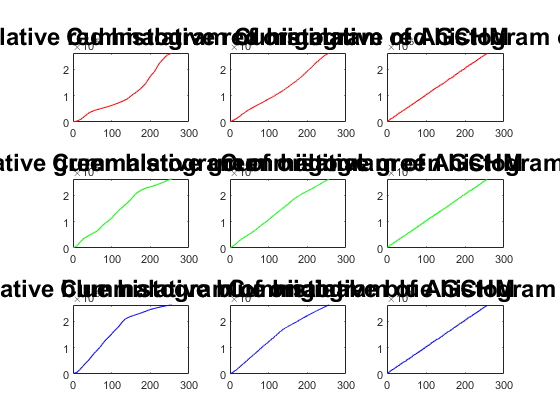

figure;
subplot(3,3,1);
plot(cumsum(imhist(imgColor(:,:,1))),'r');
title('\fontsize{18}Cummalative red histogram of original');
subplot(3,3,2);
plot(cumsum(imhist(imgEnchancedColor(:,:,1))),'r');
title('\fontsize{18}Cummalative red histogram of AGCHM');
subplot(3,3,3);
plot(cumsum(imhist(imgHisteqColor(:,:,1))),'r');
title('\fontsize{18}Cummalative red histogram of histeq');
subplot(3,3,4);
plot(cumsum(imhist(imgColor(:,:,2))),'g');
title('\fontsize{18}Cummalative green histogram of original');
subplot(3,3,5);
plot(cumsum(imhist(imgEnchancedColor(:,:,2))),'g');
title('\fontsize{18}Cummalative green histogram of AGCHM');
subplot(3,3,6);
plot(cumsum(imhist(imgHisteqColor(:,:,2))),'g');
title('\fontsize{18}Cummalative green histogram of histeq');
subplot(3,3,7);
plot(cumsum(imhist(imgColor(:,:,3))),'b');
title('\fontsize{18}Cummalative blue histogram of original');
subplot(3,3,8);
plot(cumsum(imhist(imgEnchancedColor(:,:,3))),'b');
title('\fontsize{18}Cummalative blue histogram of AGCHM');
subplot(3,3,9);
plot(cumsum(imhist(imgHisteqColor(:,:,3))),'b');
title('\fontsize{18}Cummalative blue histogram of histeq');